t = [0:300 500.5:700.5];

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


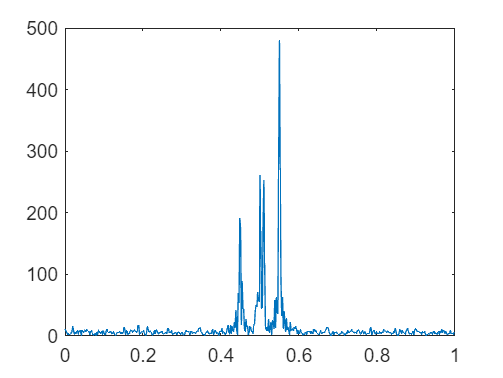

S = 2*sin(0.1*pi*t) + sin(0.02*pi*t);
tr = 0:300;
Sr = 2*sin(0.1*pi*tr) + sin(0.02*pi*tr);
X = S + rand(size(t));
Y = fftshift(nufft(X,t));
Yr = fftshift(fft(Sr,length(tr)));
n = length(t);
f = (0:n-1)/n;
plot(f,abs(Y))

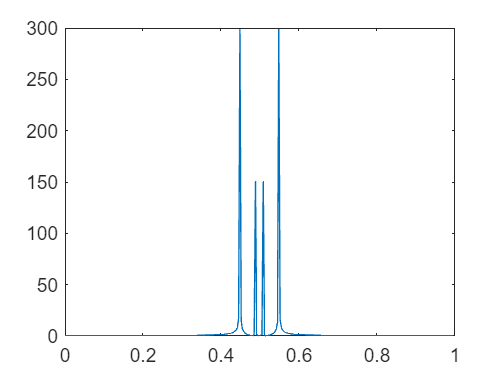

nr = length(tr);
fr = (0:nr-1)/nr;
plot(fr, abs(Yr))